# **Inverse Kinematics Demo in SE3 **

### **Resolved Rate Control**

clc;clear
[filepath,~,~] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(filepath);
addpath(fullfile(filepath,'myfunc'),'-begin')

### Find "error" between 2 transformation matrix ref to World Frame

$F_{\textrm{move}} =\left\lbrack \begin{array}{cc}
R_{\textrm{move}}  & P_{\textrm{move}} \\
0 & 1
\end{array}\right\rbrack$, $F_{\textrm{ref}} =\left\lbrack \begin{array}{cc}
R_{\textrm{ref}}  & P_{\textrm{ref}} \\
0 & 1
\end{array}\right\rbrack$

Define "error":


$$\Delta T=\left\lbrack \begin{array}{cc}
\Delta R & \Delta P\\
0 & 1
\end{array}\right\rbrack$$


**Find relation between **$F_{\textrm{move}}$** and **$F_{\textrm{ref}}$**  ref to World Frame:**


$$\Delta P=P_{\textrm{ref}} -P_{\textrm{move}}$$



$$R_{\textrm{ref}} =\Delta R\cdot R_{\textrm{move}}$$



$$\Delta R=R_{\textrm{ref}} \cdot {\left(R_{\textrm{move}} \right)}^T$$



$$\Delta R=\exp \left({\left(\vec{\omega} \cdot \theta \right)}^{\Lambda } \right)$$



$$\left\lbrace \begin{array}{ll}
\Delta P=P_{\textrm{ref}} -P_{\textrm{move}}  & \textrm{translation}\\
\Delta R=R_{\textrm{ref}} \cdot {\left(R_{\textrm{move}} \right)}^T  & \textrm{rotation}
\end{array}\right.$$


**Find relation between **$F_{\textrm{move}}$** and **$F_{\textrm{ref}}$**  ref to Body Frame:**


$$R_{\textrm{move}} \cdot \Delta R=R_{\textrm{ref}}$$



$$\Delta R={\left(R_{\textrm{move}} \right)}^T \cdot R_{\textrm{ref}}$$



$$\left\lbrace \begin{array}{ll}
\Delta P={\left(R_{\textrm{move}} \right)}^T \cdot \left(P_{\textrm{ref}} -P_{\textrm{move}} \right) & \textrm{translation}\\
\Delta R={\left(R_{\textrm{move}} \right)}^T \cdot R_{\textrm{ref}}  & \textrm{rotation}
\end{array}\right.$$


**Iteration**


$$\left\lbrack \begin{array}{c}
\Delta p\\
\Delta \omega 
\end{array}\right\rbrack =J\left(\vec{\theta} \right)\cdot \Delta \vec{\theta} =\left\lbrack \begin{array}{c}
J_{\textrm{pos}} \\
J_{\textrm{orit}} 
\end{array}\right\rbrack \cdot \Delta \vec{\theta}$$



$$\Delta \vec{\theta} ={\left\lbrack \begin{array}{c}
J_{\textrm{pos}} \\
J_{\textrm{orit}} 
\end{array}\right\rbrack }^{-1} \cdot \left\lbrack \begin{array}{c}
\Delta p\\
\Delta \omega 
\end{array}\right\rbrack$$


### Robot Model

kinV = zeros(3,10);
kinV(3,:) = 0.2;
tcp = [0.1;0;0.2];
axisnum = size(kinV,2);

### Input

maxloop = 200;
k = 0.1; % Learning Rate
max_step = ones(axisnum*3,1)*0.5/180*pi.*[-1,1]; % Max Rotation Angle for Each Step
posonly = false; % Only Control the Position
JacobTranspose = false; % Use Jacobian Transpose

### Initial Pose and Goal Pose

ag0 = ones(axisnum,3) * 0;
ag0 = ag0/180*pi;


ag1 = ones(axisnum,3) * 15;
ag1 = ag1/180*pi;
ag1(7:end,2) = -ag1(7:end,2);
ag1(3:5,1) = -ag1(3:5,1);

T_cum = kineRob(ag0,kinV,tcp);
rob0 = reshape(T_cum(1:3,4,:),3,[]);
base = [[0;0;0],rob0(:,1)];

T_cum = kineRob(ag1,kinV,tcp);
rob1 = reshape(T_cum(1:3,4,:),3,[]);
T_desired = T_cum(:,:,end);

**Plot Initial Pose and Goal Pose**

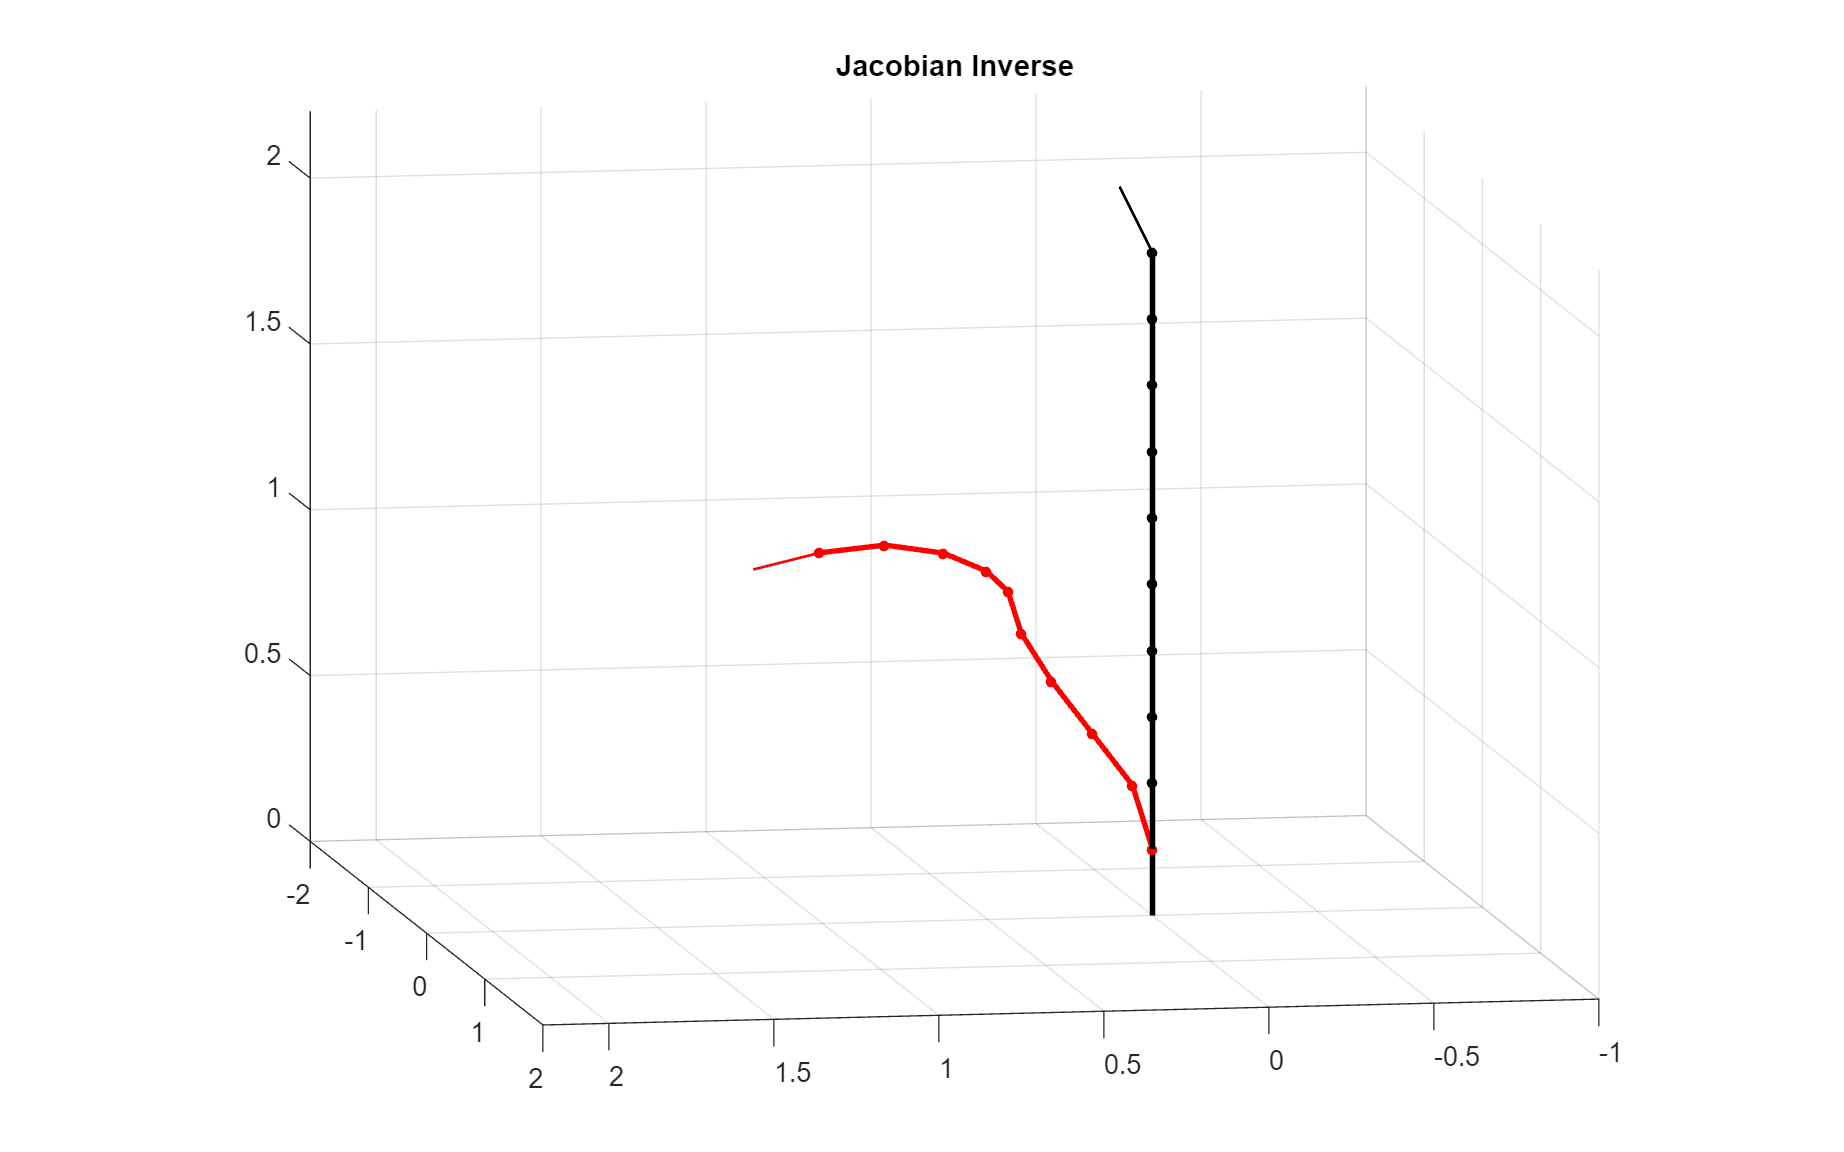

f = figure;
plot3(rob0(1,1:end-1),rob0(2,1:end-1),rob0(3,1:end-1),'o-k','MarkerFaceColor','k','LineWidth',2,'MarkerSize',2); hold on
plot3(base(1,:),base(2,:),base(3,:),'-k','LineWidth',2); hold on
plot3(rob0(1,end-1:end),rob0(2,end-1:end),rob0(3,end-1:end),'-k','MarkerFaceColor','k','LineWidth',1); hold on
plot3(rob1(1,1:end-1),rob1(2,1:end-1),rob1(3,1:end-1),'o-r','MarkerFaceColor','r','LineWidth',2,'MarkerSize',2); hold on
plot3(rob1(1,end-1:end),rob1(2,end-1:end),rob1(3,end-1:end),'-r','LineWidth',1); hold on
p1 = plot3(NaN,NaN,NaN,'o-b','MarkerFaceColor','b','LineWidth',2,'MarkerSize',2); hold on
p2 = plot3(NaN,NaN,NaN,'-b','MarkerFaceColor','r','LineWidth',1); hold on
p3 = plot3(NaN,NaN,NaN,':','Color',[0.9290 0.6940 0.1250],'LineWidth',2); hold on
grid on
axis equal
if posonly
    str1 = ' (Position Only)';
else
    str1 = '';
end
if JacobTranspose
    str2 = ' Transpose';
else
    str2 = ' Inverse';
end
title(['Jacobian',str1,str2])
zlim([0,2.2]);
xlim([-1,2.2]);
ylim([-2,2])
set(f,'Units','normalized','Position',[0,0,0.6,0.6])

view([170 8])

### Resolved Rate Control Loop

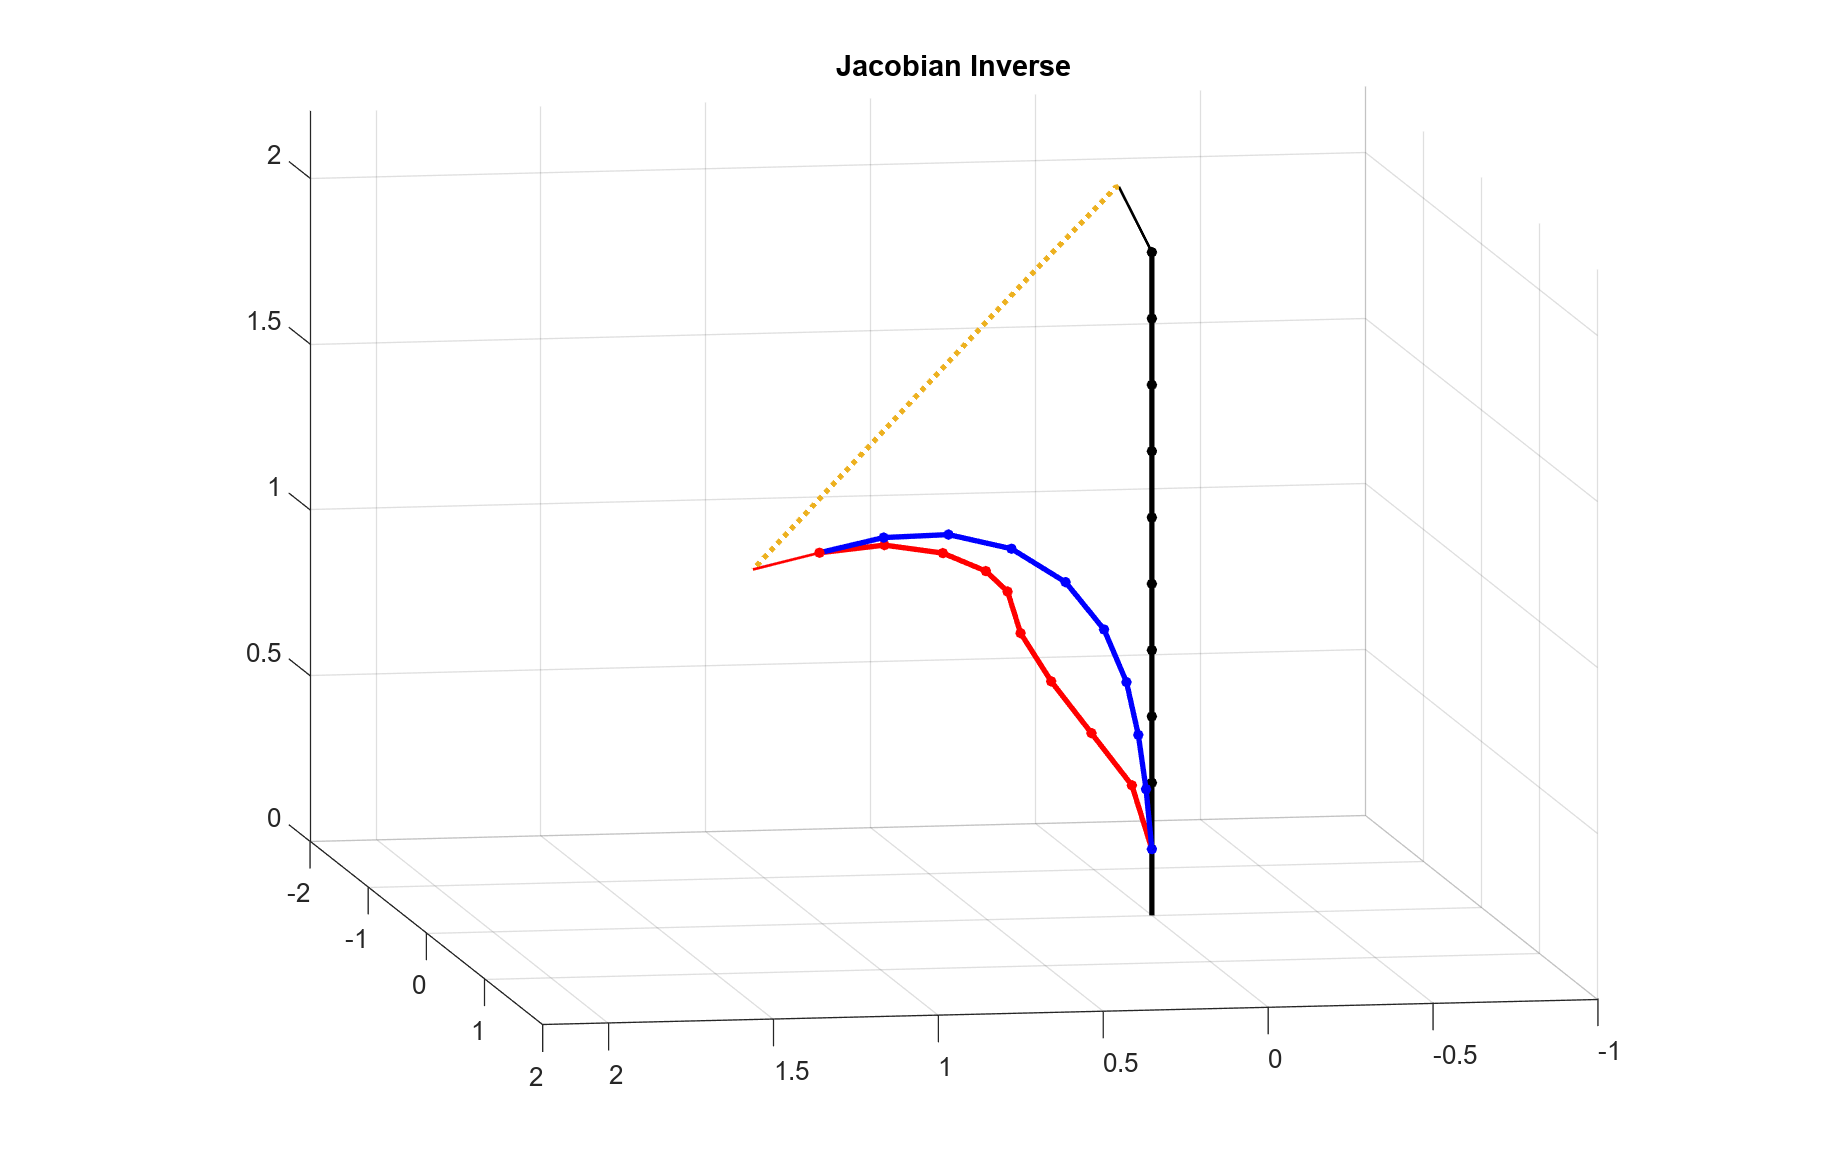

ag = ag0;
path = NaN(3,maxloop);

for i = 1:maxloop
    T_cum = kineRob(ag,kinV,tcp);

    % fwd kine
    robc = reshape(T_cum(1:3,4,:),3,[]);

    % update plot
    path(:,i) = robc(:,end);
    p1.XData = robc(1,1:end-1);
    p1.YData = robc(2,1:end-1);
    p1.ZData = robc(3,1:end-1);
    p2.XData = robc(1,end-1:end);
    p2.YData = robc(2,end-1:end);
    p2.ZData = robc(3,end-1:end);
    p3.XData = path(1,:);
    p3.YData = path(2,:);
    p3.ZData = path(3,:);
    drawnow;

    % jacobian
    J0 = jacob0_rot3(T_cum);

    % matrix difference
    [dp,dw] = diffSE3(T_desired,T_cum(:,:,end),'world');
    e = [dp;dw];

    % Stop Iteration
    % pos only
    if posonly
        if norm(dp)<=1/1000/10
            break
        end
        J0 = J0(1:3,:);
        e = dp;
    else
        if norm(dp)<=1/1000/10 && norm(dw)*180/pi<=0.1
            break
        end
    end

    % Jacobian Inverse or Transpose, get step
    if JacobTranspose
        dag = k * (J0' * e);
    else
        dag = k * (pinv(J0) * e);
    end

    % update joint angle
    dag = bound2range(dag,max_step,true);
    dag = reshape(dag,3,[])';
    ag = ag + dag;
    
end